M = 2;
numBits = 1e3;
chipRate = 10;
snr = 10;
fs = 1000;

% Generate random bits
dataBits = randi([0 1], numBits, 1);

% BPSK modulation
modulatedSignal = dataBits*2 -1;

% Generate PN Sequence
pnSequence = randi([0 1], numBits*chipRate, 1);
pnSequence = pnSequence*2 - 1;

% Spread the Signal
spreadSignal = repelem(modulatedSignal,chipRate).*pnSequence;

% Transmit over AWGN channel
recievedSignal = awgn(spreadSignal, snr, 'measured');

% Despread the signal
despreadSignal = recievedSignal .* pnSequence

despreadSignal =     1.0332
    0.8293
    0.5106
    1.0119
    1.0963
    0.8131
    1.3512
    0.9254
    1.3725
    0.7194


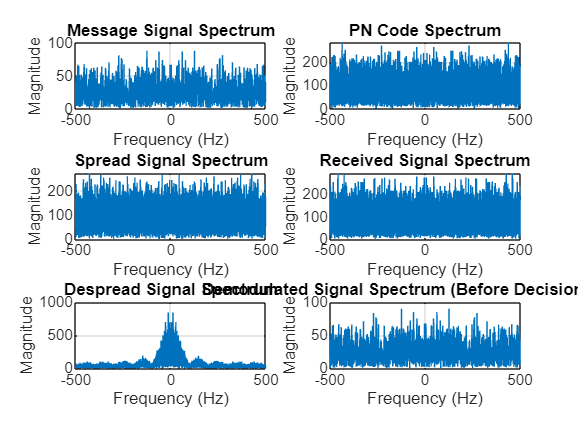

despreadBits = sum(reshape(despreadSignal, chipRate, numBits),1)' / chipRate;

% Demodulate Signal
recievedBits = despreadBits > 0;

% Calculate bit error rate
BER_DSSS = sum(dataBits ~= recievedBits) / numBits;

% Calculate FFT for plotting spectra
n = length(spreadSignal);
frequencies = (-n/2 : n/2 -1) * (fs/n);

% Message Signal Spectrum
messageSpectrum = fftshift(fft(modulatedSignal,n));

%PN code spectrum
pnSpectrum = fftshift(fft(pnSequence,n));

%Spread Signal spectrum
spreadSignalSpectrum = fftshift(fft(spreadSignal,n));

% Received signal spectrum
receivedSignalSpectrum = fftshift(fft(recievedSignal, n));

% Despread signal spectrum
despreadSignalSpectrum = fftshift(fft(despreadSignal, n));

% Demodulated signal spectrum (before decision device)
demodulatedSignalSpectrum = fftshift(fft(despreadBits, n));

% Plotting
figure;
subplot(3,2,1);
plot(frequencies, abs(messageSpectrum));
title('Message Signal Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,2,2);
plot(frequencies, abs(pnSpectrum));
title('PN Code Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,2,3);
plot(frequencies, abs(spreadSignalSpectrum));
title('Spread Signal Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,2,4);
plot(frequencies, abs(receivedSignalSpectrum));
title('Received Signal Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,2,5);
plot(frequencies, abs(despreadSignalSpectrum));
title('Despread Signal Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(3,2,6);
plot(frequencies, abs(demodulatedSignalSpectrum));
title('Demodulated Signal Spectrum (Before Decision Device)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;